# Group Project: Virtual MRI Scanner

# Phantom Creation

% Generates a phantom image
function matrix = generatePhantoms(size, ellipses, addRectangle)
    matrix = phantom(ellipses, size);

    % Adds a rectangle to the matrix by defining a rectangular region in
    % which the signal intensity for pixels in this region is set appropriately
    if addRectangle == true
        [x, y] = deal(size);
        midX = x / 2;
        deltaX = x / 15;
        leftXBoundary = midX - deltaX;
        rightXBoundary= midX + deltaX;
    
        midY = y / 2;
        deltaY = y / 3.5;
        topYBoundary = midY - deltaY;
        bottomYBoundary= midY + deltaY;

        for i=1:x
            for j=1:y
                % Ensure current coordinate is within the rectangle's boundaries
                if (j >= leftXBoundary) && (j <= rightXBoundary) && (i >= topYBoundary) && (i <= bottomYBoundary)
                    matrix(i, j) = 1;
                end
            end
        end
    end
    %figure, imshow(matrix)
    figure;
    imagesc(matrix);
    colormap("gray");
    colorbar;
end

phantomOne = [0.5 0.75 0.75 0 0 0];   % Outer circle ellipse (rectangle region added below)

phantomTwo = [0.5 0.75  0.75   0    0 0 % Outer circle ellipse
              1.0 0.20  0.20   0.5  0 0 % Right most inner circle ellipse
              1.0 0.15  0.15   0.1  0 0 % Second from right circle ellipse
              1.0 0.10  0.10  -0.2  0 0 % Third from right circle ellipse
              1.0 0.05  0.05  -0.4  0 0 % Fourth from right circle ellipse
              1.0 0.025 0.025 -0.52 0 0 % Left most inner circle ellipse
             ];

% Set size
N = 256; % GUI MODIFIED VARIABLE

% Generate phantoms
disp("Phantom One")

Phantom One


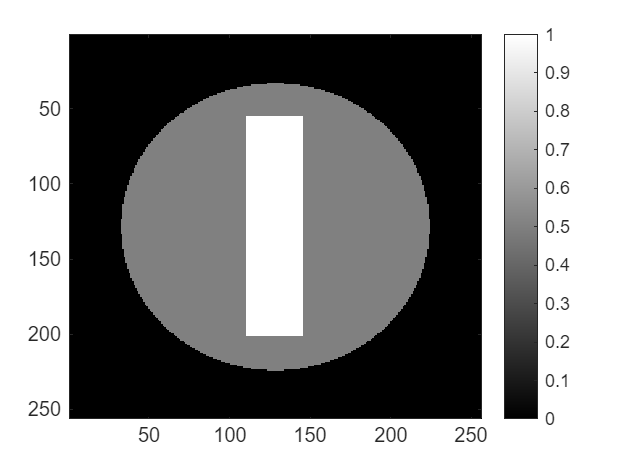

matrixOne = generatePhantoms(N, phantomOne, true);


disp("Phantom Two")

Phantom Two


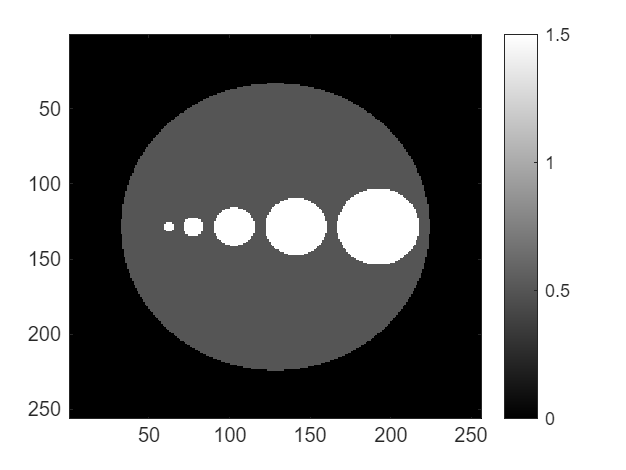

matrixTwo = generatePhantoms(N, phantomTwo, false);


% Acquisition time parameter (modifiable via GUI or script)
acquisitionTime = 0.5; % Half the full acquisition time


# K-Space

Phantom 1 Forward FFT

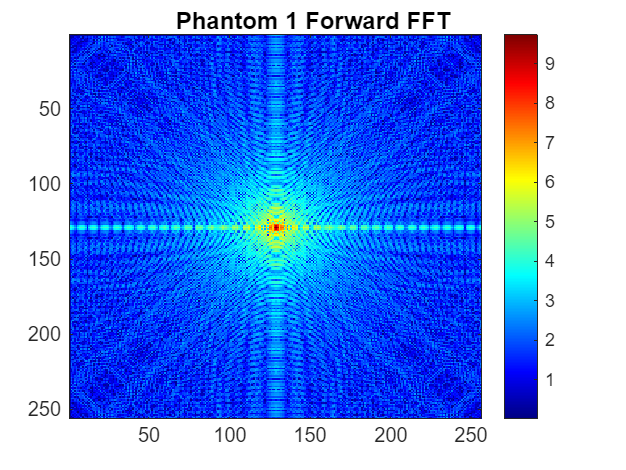

% Generate and show the k-space of a phantom
function kspace = fftTransform(matrix, direction, text,  parameters)
    legendText = "";
    if direction == "forward"
        color = "jet";
        fprintf(text);
        kspace = fft2(matrix);
        imageArray = log(1 + abs(fftshift(kspace)));
    else
        color = "gray";
        fprintf(text);
        kspace = ifft2(matrix);
        imageArray = abs(kspace);
    end

    % Cartesian
    if (length(parameters) == 5)
        compartment1 = sprintf("Size: %d", parameters(1));
        compartment2 = sprintf("Width: %d", parameters(2));
        compartment3 = sprintf("Line Points: %d", parameters(3));
        compartment4 = sprintf("Lines: %d", parameters(4));
        compartment5 = sprintf("Swap: %d", parameters(5));
        legendText = compartment1 + newline + compartment2 + newline + compartment3 + newline + compartment4 + newline + compartment5;

    % Radial
    elseif (length(parameters) == 3) 
        compartment1 = sprintf("Size: %d", parameters(1));
        compartment2 = sprintf("Radial Line Points: %d", parameters(2));
        compartment3 = sprintf("Radial Lines: %d", parameters(3));
        legendText = compartment1 + newline + compartment2 + newline + compartment3;
    end

    figure;
    sgtitle(text, 'FontWeight', 'bold');
    imagesc(imageArray);
    if (legendText ~= "")
        annotation('textbox', [.005 .1 0 0],'String', legendText, 'FitBoxToText','on');
    end
    colormap(color);
    colorbar;
end

% Get FFT images for both phantoms
fftOne = fftTransform(matrixOne, "forward", "Phantom 1 Forward FFT", "");

Phantom 2 Forward FFT 

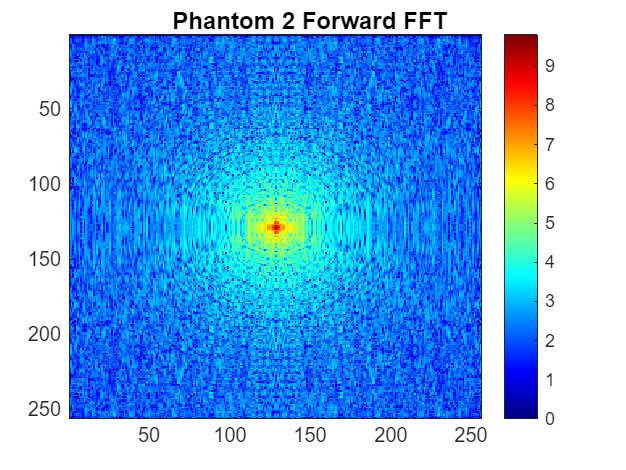

fftTwo = fftTransform(matrixTwo, "forward", "Phantom 2 Forward FFT ", "");

Phantom 1 Inverse FFT

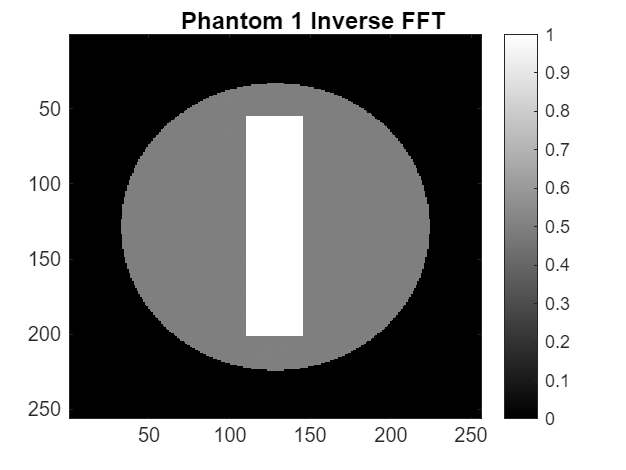


% Run FFT inverse to show that it all works correctly
fftOneReverse = fftTransform(fftOne, "inverse", "Phantom 1 Inverse FFT", "");

Phantom 2 Inverse FFT

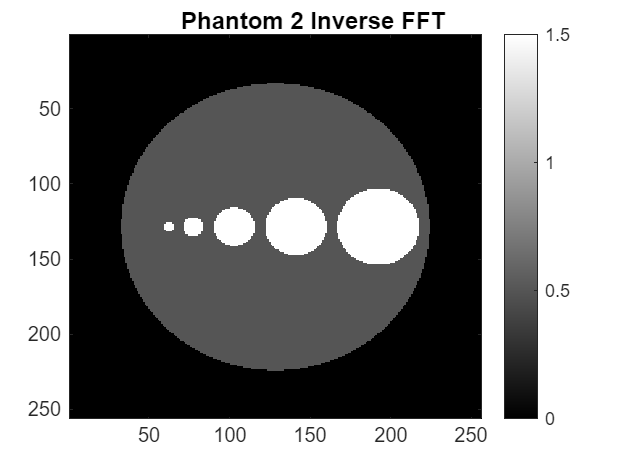

fftTwoReverse = fftTransform(fftTwo, "inverse", "Phantom 2 Inverse FFT", "");

# Cartesian Acquisition Trajectory

% Cartesian Acquisition Trajectory which returns final image matrix given user parameters
function reconstruction = cartesianSample(matrix, width, pointDensity, lineDensity, swap, acquisitionTime)
    [rows,cols] = size(matrix);
    reconstruction = zeros(rows, cols);

    % Scale the point and line density based on acquisition time
    pointDensity = round(pointDensity * acquisitionTime);
    lineDensity = round(lineDensity * acquisitionTime);

    if swap == true
        rowSpacing   = ceil(cols / pointDensity);
        pointSpacing = ceil(rows / lineDensity);
    else
        rowSpacing   = ceil(rows / lineDensity);
        pointSpacing = ceil(cols / pointDensity);
    end

    for i=1:rowSpacing:width
        for j=1:pointSpacing:width

            if swap == true
                point = matrix(j,i);
            else
                point = matrix(i,j);
            end
            reconstruction(i, j) = point;
        end
    end
end

Cartesian - Phantom 1 Inverse FFT

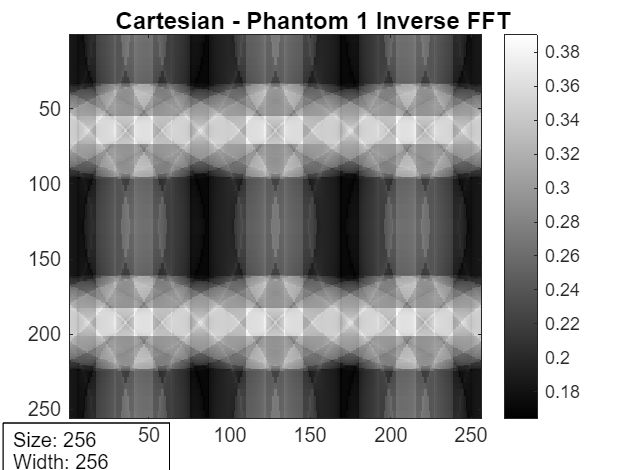

% This must be modified to work with the GUI to set applicable parameters
% The following are variables to be set via the GUI:
matrixWidth                    = N; % int GUI MODIFIED VARIABLE (CANNOT BE LARGER THAN N)
linePointDensity               = 50; % int GUI MODIFIED VARIABLE
horizontalLineDensity          = 256; % int GUI MODIFIED VARIABLE
swapHorizontalAndVerticalLines = false; % boolean GUI MODIFIED VARIABLE

% Parameters to show in reconstruction
cartesianInputParameters = [N, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines];

% Reconstruct both phantoms according to user parameters
reconstructionOneCartesian = cartesianSample(fftOne, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines, acquisitionTime);
postFFTOneCartesian = fftTransform(reconstructionOneCartesian, "inverse", "Cartesian - Phantom 1 Inverse FFT", cartesianInputParameters);

Cartesian - Phantom 2 Inverse FFT

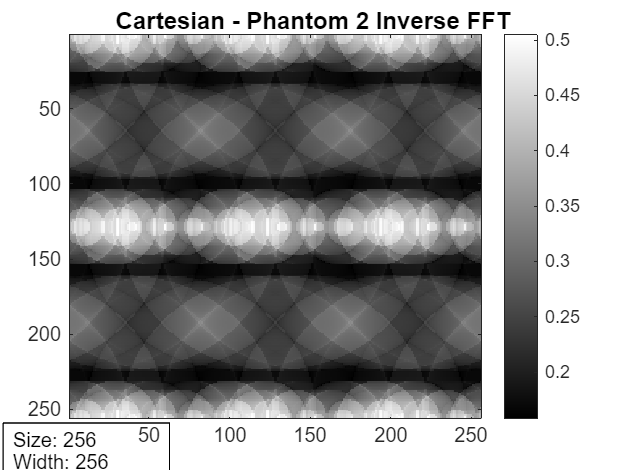


reconstructionTwoCartesian = cartesianSample(fftTwo, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines, acquisitionTime);
postFFTTwoCartesian = fftTransform(reconstructionTwoCartesian, "inverse", "Cartesian - Phantom 2 Inverse FFT", cartesianInputParameters);

# Radial Acquisition Trajectory

% Radial Acquisition Trajectory which returns final image matrix given
function reconstruction = radialSample(kspace, numRadialLines, numPointsPerLine, acquisitionTime)
    [rows, cols] = size(kspace);
    centerX = rows / 2;
    centerY = cols / 2;
    reconstruction = zeros(rows, cols);

    % Scale the radial lines and points per line based on acquisition time
    numRadialLines = round(numRadialLines * acquisitionTime);
    numPointsPerLine = round(numPointsPerLine * acquisitionTime);

    % Calculate the angle between each radial line
    angleIncrement = 2 * pi / numRadialLines;

    for n = 0:numRadialLines-1
        angle = n * angleIncrement;
        for p = 1:numPointsPerLine
            % Calculate the coordinates of the point on the radial line
            x = round(centerX + (p - numPointsPerLine/2) * cos(angle));
            y = round(centerY + (p - numPointsPerLine/2) * sin(angle));

            % Ensure the coordinates are within the grid boundaries
            if x > 0 && x <= rows && y > 0 && y <= cols
                reconstruction(x, y) = kspace(x, y);
            end
        end
    end
end

Radial - Phantom 1 Inverse FFT

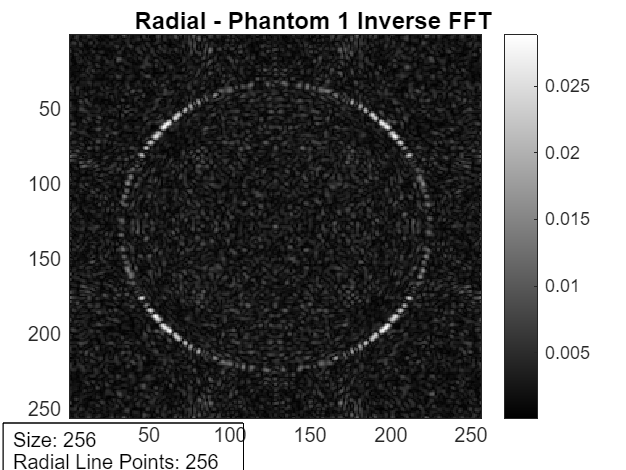

% This must be modified to work with the GUI to set applicable parameters
% The following are variables to be set via the GUI:
numRadialLines   = 50;  % int GUI MODIFIED VARIABLE
numPointsPerLine = 256; % int GUI MODIFIED VARIABLE

% Parameters to show in reconstruction
radialInputParameters = [N, numPointsPerLine, numRadialLines];

% Reconstruct both phantoms using radial sampling
reconstructionOneRadial = radialSample(fftOne, numRadialLines, numPointsPerLine, acquisitionTime);
postFFTOneRadial = fftTransform(reconstructionOneRadial, "inverse", "Radial - Phantom 1 Inverse FFT", radialInputParameters);

Radial - Phantom 2 Inverse FFT

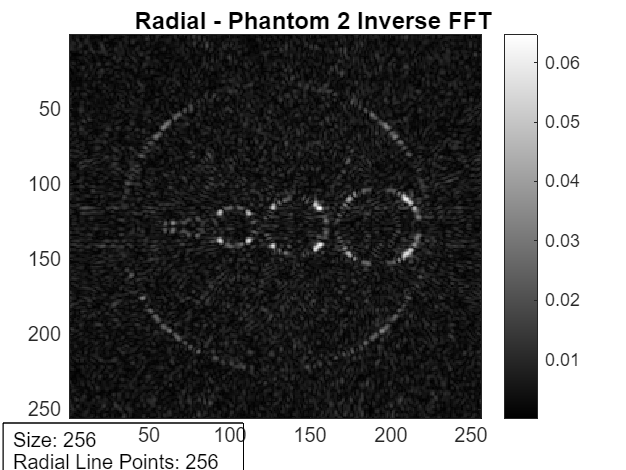


reconstructionTwoRadial = radialSample(fftTwo, numRadialLines, numPointsPerLine, acquisitionTime);
postFFTTwoRadial = fftTransform(reconstructionTwoRadial, "inverse", "Radial - Phantom 2 Inverse FFT", radialInputParameters);

# Image Analysis

% Signal Intensity and Contrast
% Return if point is out of matrix boundary
function result = isOutOfBounds(point, size)
    x = point(1);
    y = point(2);

    result = (x < 1) || (y < 1) || (x > size) || (y > size);
end

% Return if point is out of region boundary
function result = isOutOfRegion(center, point, radius)
    x = center(1);
    y = center(2);

    x1 = point(1);
    y1 = point(2);

    distance = sqrt((x - x1)^2 + (y - y1)^2);
    result = distance > radius;
end

% To calculate SI difference of two regions, we first get each region's average SI
function average = calculateAverageSignalIntensityOfRegion(matrix, radius, position)
    dimensions = size(matrix);
    length = dimensions(1);
    x = position(1);
    y = position(2);
    
    % Box containing region
    leftBoundary   = x - radius;
    rightBoundary  = x + radius;
    topBoundary    = y - radius;
    bottomBoundary = y + radius;

    % Running sum to calculate average
    sum = 0;
    count = 0;

    % Get SI for all points within the boundary to later calculate the region's average SI
    for i=leftBoundary:rightBoundary
        for j=topBoundary:bottomBoundary
            point = [i, j];
            % Ensure point is within matrix and region boundaries
            if (isOutOfRegion(position, point, radius) || isOutOfBounds(point, length))
                continue;
            end

            % Increment sum and count to average later (uses abs() to get
            % magnitude of signal intensity, especially for when the matrix
            % has complex numbers
            sum = sum + abs(matrix(i, j));
            count = count + 1;
        end
    end

    average = sum / count;
end

% Returns the difference of SI of two regions of given radius for a given matrix
function difference = signalIntensityDifference(matrix, radius, positionOne, positionTwo)
    averageOfRegionOne = calculateAverageSignalIntensityOfRegion(matrix, radius, positionOne);
    averageOfRegionTwo = calculateAverageSignalIntensityOfRegion(matrix, radius, positionTwo);

    % Calculate difference
    if averageOfRegionOne > averageOfRegionTwo
        difference = averageOfRegionOne - averageOfRegionTwo;
    else
        difference = averageOfRegionTwo - averageOfRegionOne;
    end
end

% Calculates the difference of SI averages between 2 regions of a matrix
radius = 50; % int GUI MODIFIED VARIABLE (maybe the radius should be limited according to N)
[x1, y1] = deal(0, 0); % int GUI MODIFIED VARIABLE (let the user pick two ints between 1 and N)
[x2, y2] = deal(100, 100); % int GUI MODIFIED VARIABLE (let the user pick two ints between 1 and N)


% Below to be removed such that not all differences be shown. For sure the
% differences in the test phantoms should be shown against the difference
% in the output phantom

testDifferenceOne          = signalIntensityDifference(matrixOne, radius, [x1, y1], [x2, y2])

testDifferenceOne = 0.6747

testDifferenceOneCartesian = signalIntensityDifference(postFFTOneCartesian, radius, [x1, y1], [x2, y2])

testDifferenceOneCartesian = 0.0277

testDifferenceOneRadial    = signalIntensityDifference(postFFTOneRadial, radius, [x1, y1], [x2, y2])

testDifferenceOneRadial = 3.9009e-04


testDifferenceTwo          = signalIntensityDifference(matrixTwo, radius, [x1, y1], [x2, y2])

testDifferenceTwo = 0.6517

testDifferenceTwoCartesian = signalIntensityDifference(postFFTTwoCartesian, radius, [x1, y1], [x2, y2])

testDifferenceTwoCartesian = 0.0106

testDifferenceTwoRadial    = signalIntensityDifference(postFFTTwoRadial, radius, [x1, y1], [x2, y2])

testDifferenceTwoRadial = 0.0020

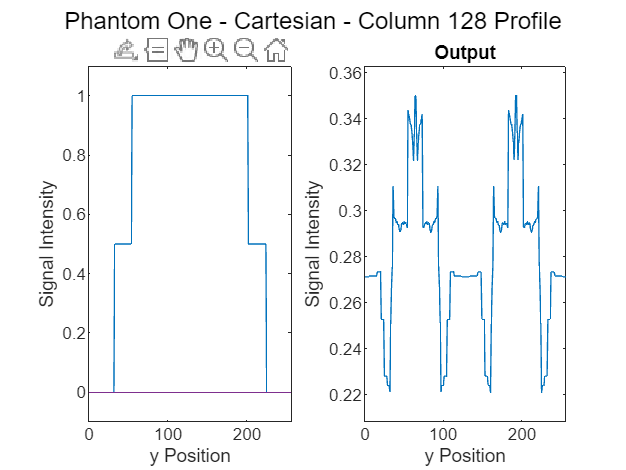

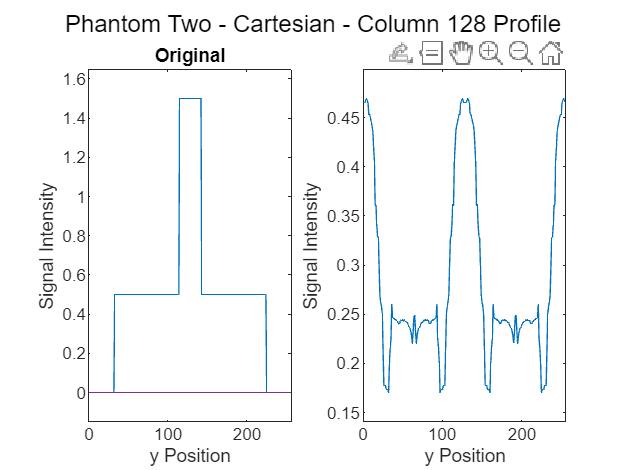

% Signal Intensity Profiles
% Returns an signal intensity array and other similar data to be plotted for a given matrix
function [signalIntensities, minSI, maxSI, xLabel, titleText] = getSignalIntensities(matrix, direction, position)
    [x, y] = size(matrix);
    signalIntensities = zeros(x);
    minSI = inf;
    maxSI = -inf;

    if (direction == "horizontal")
        xLabel = "x Position";
        titleText = "Row " + position + " Profile";

        for i=1:x
            signalIntensity = abs(matrix(position, i));
            signalIntensities(i) = signalIntensity;
            
            % Set min/maxSI accordingly
            if (signalIntensity < minSI)
                minSI = signalIntensity;
            end
            if (signalIntensity > maxSI)
                maxSI = signalIntensity;
            end
        end
    elseif (direction == "vertical")
        xLabel = "y Position";
        titleText = "Column " + position + " Profile";

        for i=1:y
            signalIntensity = abs(matrix(i, position));
            signalIntensities(i) = signalIntensity;

            % Set min/maxSI accordingly
            if (signalIntensity < minSI)
                minSI = signalIntensity;
            end
            if (signalIntensity > maxSI)
                maxSI = signalIntensity;
            end
        end
    end

    range = maxSI - minSI;
    minSI = minSI - (range * .1);
    maxSI = maxSI + (range * .1);
    if minSI == maxSI
        minSI = maxSI - 1;
    end
end

% Generates a pair of plots plotting SI vs Position
function signalIntensityVsPositionGraph(matrixOne, matrixTwo, direction, position, type)
    [x1, y1] = size(matrixOne);
    [x2, y2] = size(matrixTwo);

    [signalIntensitiesOne, minSIOne, maxSIOne, xLabelOne, titleTextOne] = getSignalIntensities(matrixOne, direction, position);
    [signalIntensitiesTwo, minSITwo, maxSITwo, xLabelTwo, titleTextTwo] = getSignalIntensities(matrixTwo, direction, position);

    % Plot figure
    figure;
    sgtitle(type + " - " + titleTextOne);
    subplot(1, 2, 1); plot(signalIntensitiesOne); xlabel(xLabelOne); ylabel("Signal Intensity"); ylim([minSIOne maxSIOne]); xlim([0 x1]); title("Original");
    subplot(1, 2, 2); plot(signalIntensitiesTwo); xlabel(xLabelTwo); ylabel("Signal Intensity"); ylim([minSITwo maxSITwo]); xlim([0 x2]); title("Output");
end

% We need the GUI to have the ability to allow the user to select position and direction
position = floor((N + 1) / 2); % int CANT BE LARGER THAN N GUI MODIFIED VARIABLE
direction = "vertical"; % string (could be a boolean toggle on GUI) GUI MODIFIED VARIABLE [values: either "horizontal" or "vertical"]

% Fix to be whatever variable you have in the GUI
cartesianOrRadial = "cartesian";

if (cartesianOrRadial == "cartesian")
    signalIntensityVsPositionGraph(matrixOne, postFFTOneCartesian, direction, position, "Phantom One - Cartesian");
    signalIntensityVsPositionGraph(matrixTwo, postFFTTwoCartesian, direction, position, "Phantom Two - Cartesian");
else
    signalIntensityVsPositionGraph(matrixOne, postFFTOneRadial, direction, position, "Phantom One - Radial");
    signalIntensityVsPositionGraph(matrixTwo, postFFTTwoRadial, direction, position, "Phantom One - Radial");
end